# **The Physics of the Damped Harmonic Oscillator**

This example explores the physics of the damped harmonic oscillator by solving the equations of motion in the case of no driving forces. This example investigates the cases of under-, over-, and critical-damping.

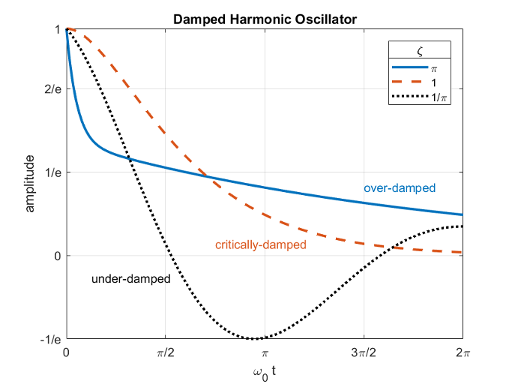

## Contents

- Derive Equation of Motion

- Solve the Equation of Motion (F = 0)

- Underdamped Case ($\zeta < 1$)

- Overdamped Case ($\zeta > 1$)

- Critically Damped Case ($\zeta = 1$)

- Conclusion

## 1. Derive Equation of Motion

Consider a forced harmonic oscillator with damping shown below. Model the resistance force as proportional to the speed with which the oscillator moves. 

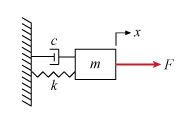

Define the equation of motion where

- $m$ is the mass

- $c$ is the damping coefficient

- $k$ is the spring constant

- $F$ is a driving force

syms x(t) m c k F(t)
eq = m*diff(x,t,t) + c*diff(x,t) + k*x == F

$$eq(t) = m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+c\,\frac{\partial }{\partial t}x\left(t\right)+k\,x\left(t\right)=F\left(t\right)$$

Rewrite the equation using $c=m\;\gamma$ and $k=m\;\omega_0^2$.

syms gamma omega_0
eq = subs(eq, [c k], [m*gamma, m*omega_0^2])

$$eq(t) = m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\gamma \,m\,\frac{\partial }{\partial t}x\left(t\right)+m\,x\left(t\right)\,{\omega_{0}}^{2}=F\left(t\right)$$

Divide out the mass $m$. Now we have the equation in a convenient form to analyze.

eq = collect(eq, m)/m

$$eq(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\gamma \,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)\,{\omega_{0}}^{2}=\frac{F\left(t\right)}{m}$$

## 2. Solve the Equation of Motion where F = 0

Solve the equation of motion using `dsolve` in the case of no external forces where $F = 0$. Use the initial conditions of unit displacement and zero velocity.

vel = diff(x,t);
cond = [x(0) == 1, vel(0) == 0];
eq = subs(eq,F,0);
sol = dsolve(eq, cond)

$$sol = \begin{array}{l} \frac{{\mathrm{e}}^{-t\,\left(\frac{\gamma }{2}-\frac{\sigma_{1}}{2}\right)}\,\left(\gamma +\sigma_{1}\right)}{2\,\sigma_{1}}-\frac{{\mathrm{e}}^{-t\,\left(\frac{\gamma }{2}+\frac{\sigma_{1}}{2}\right)}\,\left(\gamma -\sigma_{1}\right)}{2\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\left(\gamma -2\,\omega_{0}\right)\,\left(\gamma +2\,\omega_{0}\right)} \end{array}$$

Examine how to simplify the solution by expanding it.

sol = expand(sol)

$$sol = \begin{array}{l} \frac{\sigma_{1}\,\sigma_{2}}{2}+\frac{\sigma_{1}\,{\mathrm{e}}^{\frac{t\,\sqrt{\gamma^{2}-4\,{\omega_{0}}^{2}}}{2}}}{2}-\frac{\gamma \,\sigma_{1}\,\sigma_{2}}{2\,\sqrt{\gamma^{2}-4\,{\omega_{0}}^{2}}}+\frac{\gamma \,\sigma_{1}\,{\mathrm{e}}^{\frac{t\,\sqrt{\gamma^{2}-4\,{\omega_{0}}^{2}}}{2}}}{2\,\sqrt{\gamma^{2}-4\,{\omega_{0}}^{2}}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{\gamma \,t}{2}}\\ \sigma_{2}={\mathrm{e}}^{-\frac{t\,\sqrt{\gamma^{2}-4\,{\omega_{0}}^{2}}}{2}} \end{array}$$

Notice that each term has a factor of $\sigma_1$, or $e^{-\gamma t / 2}$, use `collect` to gather these terms 

sol = collect(sol, exp(-gamma*t/2))

$$sol = \begin{array}{l} \left(\frac{{\mathrm{e}}^{-\sigma_{1}}}{2}+\frac{{\mathrm{e}}^{\sigma_{1}}}{2}-\frac{\gamma \,{\mathrm{e}}^{-\sigma_{1}}}{2\,\sqrt{\gamma^{2}-4\,{\omega_{0}}^{2}}}+\frac{\gamma \,{\mathrm{e}}^{\sigma_{1}}}{2\,\sqrt{\gamma^{2}-4\,{\omega_{0}}^{2}}}\right)\,{\mathrm{e}}^{-\frac{\gamma \,t}{2}}\\ \mathrm{where}\\ \sigma_{1}=\frac{t\,\sqrt{\gamma^{2}-4\,{\omega_{0}}^{2}}}{2} \end{array}$$

The term $\sqrt{\gamma^2 - 4\omega_0^2}$ appears in various parts of the solution. Rewrite it in a simpler form by introducing the damping ratio $\zeta \equiv \frac{\gamma }{2\omega_0 }$.

Substituting ζ into the term above gives: 


$$\sqrt{\gamma^2 -4\omega_0^2 }=2\omega_0 \sqrt{{\left(\frac{\gamma }{2\omega_0 }\right)}^2 -1}=2\omega_0 \sqrt{\zeta^2 -1},$$


syms zeta;
sol = subs(sol, ...
    sqrt(gamma^2 - 4*omega_0^2), ...
    2*omega_0*sqrt(zeta^2-1))

$$sol = \begin{array}{l} {\mathrm{e}}^{-\frac{\gamma \,t}{2}}\,\left(\frac{\sigma_{2}}{2}+\frac{\sigma_{1}}{2}+\frac{\gamma \,\sigma_{2}}{4\,\omega_{0}\,\sqrt{\zeta^{2}-1}}-\frac{\gamma \,\sigma_{1}}{4\,\omega_{0}\,\sqrt{\zeta^{2}-1}}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\omega_{0}\,t\,\sqrt{\zeta^{2}-1}}\\ \sigma_{2}={\mathrm{e}}^{\omega_{0}\,t\,\sqrt{\zeta^{2}-1}} \end{array}$$

Further simplify the solution by substituting $\gamma$ in terms of $\omega_0$ and $\zeta$,

sol = subs(sol, gamma, 2*zeta*omega_0)

$$sol = \begin{array}{l} {\mathrm{e}}^{-\omega_{0}\,t\,\zeta }\,\left(\frac{\sigma_{2}}{2}+\frac{\sigma_{1}}{2}+\frac{\zeta \,\sigma_{2}}{2\,\sqrt{\zeta^{2}-1}}-\frac{\zeta \,\sigma_{1}}{2\,\sqrt{\zeta^{2}-1}}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\omega_{0}\,t\,\sqrt{\zeta^{2}-1}}\\ \sigma_{2}={\mathrm{e}}^{\omega_{0}\,t\,\sqrt{\zeta^{2}-1}} \end{array}$$

We have derived the general solution for the motion of the damped harmonic oscillator with no driving forces. Next, we'll explore three special cases of the damping ratio $\zeta$ where the motion takes on simpler forms. These cases are called

- underdamped $(\zeta < 1)$,

- overdamped $(\zeta > 1)$, and

- critically damped $(\zeta = 1)$.

## 3. Underdamped Case ($\zeta < 1$)

If $\zeta < 1$, then $\sqrt{\zeta^2 - 1} = i\sqrt{1-\zeta^2}$ is purely imaginary

solUnder = subs(sol, sqrt(zeta^2-1), 1i*sqrt(1-zeta^2))

$$solUnder = \begin{array}{l} {\mathrm{e}}^{-\omega_{0}\,t\,\zeta }\,\left(\frac{\sigma_{1}}{2}+\frac{\sigma_{2}}{2}+\frac{\zeta \,\sigma_{1}\,\mathrm{i}}{2\,\sqrt{1-\zeta^{2}}}-\frac{\zeta \,\sigma_{2}\,\mathrm{i}}{2\,\sqrt{1-\zeta^{2}}}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\omega_{0}\,t\,\sqrt{1-\zeta^{2}}\,\mathrm{i}}\\ \sigma_{2}={\mathrm{e}}^{\omega_{0}\,t\,\sqrt{1-\zeta^{2}}\,\mathrm{i}} \end{array}$$

Notice the terms $e^{i\;\omega_0 \;t\sqrt{\zeta^2 -1}} \pm \;e^{-{i\;\omega }_0 \;t\sqrt{\zeta^2 -1}}$ in the above equation and recall the identity $e^{i\;x} =\cos \left(x\right)+i\;\sin \left(x\right)\ldotp$

Rewrite the solution in terms of $\cos$.

solUnder = coeffs(solUnder, zeta);
solUnder = solUnder(1);
c = exp(-omega_0 * zeta * t);
solUnder = c * rewrite(solUnder / c, 'cos')

$$solUnder = {\mathrm{e}}^{-\omega_{0}\,t\,\zeta }\,\cos\left(\omega_{0}\,t\,\sqrt{1-\zeta^{2}}\right)$$

solUnder(t, omega_0, zeta) = solUnder

$$solUnder(t, omega\_0, zeta) = {\mathrm{e}}^{-\omega_{0}\,t\,\zeta }\,\cos\left(\omega_{0}\,t\,\sqrt{1-\zeta^{2}}\right)$$

The system oscillates at a natural frequency of $\omega_0 \sqrt{1-\zeta^2}$ and decays at an exponential rate of $1/\omega_0 \, \zeta$.

Plot the solution with `fplot` as a function of $\omega_0 t$ and $\zeta$.

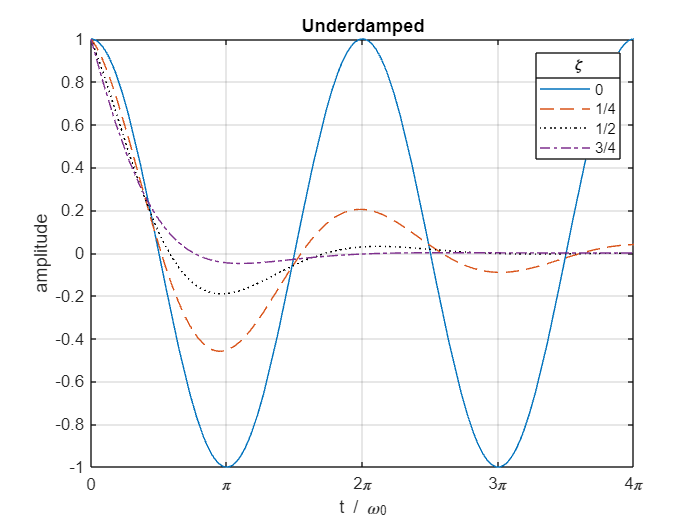

z = [0 1/4 1/2 3/4];
w = 1;
T = 4*pi;
lineStyle = {'-','--',':k','-.'};

fplot(@(t)solUnder(t, w, z(1)), [0 T], lineStyle{1});

hold on;
for k = 2:numel(z)
    fplot(@(t)solUnder(t, w, z(k)), [0 T], lineStyle{k});
end
hold off;
grid on;
xticks(T*linspace(0,1,5));
xticklabels({'0','\pi','2\pi','3\pi','4\pi'});
xlabel('t / \omega_0');
ylabel('amplitude');
lgd = legend('0','1/4','1/2','3/4');
title(lgd,'\zeta');
title('Underdamped');

## 4. Overdamped Case ($\zeta > 1$)

If $\zeta > 1$, then $\sqrt{\zeta^2 - 1}$ is purely real and the solution can be rewritten as

solOver = sol

$$solOver = \begin{array}{l} {\mathrm{e}}^{-\omega_{0}\,t\,\zeta }\,\left(\frac{\sigma_{2}}{2}+\frac{\sigma_{1}}{2}+\frac{\zeta \,\sigma_{2}}{2\,\sqrt{\zeta^{2}-1}}-\frac{\zeta \,\sigma_{1}}{2\,\sqrt{\zeta^{2}-1}}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\omega_{0}\,t\,\sqrt{\zeta^{2}-1}}\\ \sigma_{2}={\mathrm{e}}^{\omega_{0}\,t\,\sqrt{\zeta^{2}-1}} \end{array}$$

solOver = coeffs(solOver, zeta);
solOver = solOver(1)

$$solOver = {\mathrm{e}}^{-\omega_{0}\,t\,\zeta }\,\left(\frac{{\mathrm{e}}^{\omega_{0}\,t\,\sqrt{\zeta^{2}-1}}}{2}+\frac{{\mathrm{e}}^{-\omega_{0}\,t\,\sqrt{\zeta^{2}-1}}}{2}\right)$$

Notice the terms $\frac{\left(e^{\omega_0 t\sqrt{\zeta^2 -1}} +e^{-\omega_0 t\sqrt{\zeta^2 -1}} \right)}{2}$ and recall the identity $\cosh \left(x\right)=\frac{e^x +e^{-x} }{2}$.

Rewrite the expression in terms of $\cosh$.

c = exp(-omega_0*t*zeta);
solOver = c*rewrite(solOver / c, 'cosh')

$$solOver = \cosh\left(\omega_{0}\,t\,\sqrt{\zeta^{2}-1}\right)\,{\mathrm{e}}^{-\omega_{0}\,t\,\zeta }$$

solOver(t, omega_0, zeta) = solOver

$$solOver(t, omega\_0, zeta) = \cosh\left(\omega_{0}\,t\,\sqrt{\zeta^{2}-1}\right)\,{\mathrm{e}}^{-\omega_{0}\,t\,\zeta }$$

Plot the solution to see that it decays without oscillating.

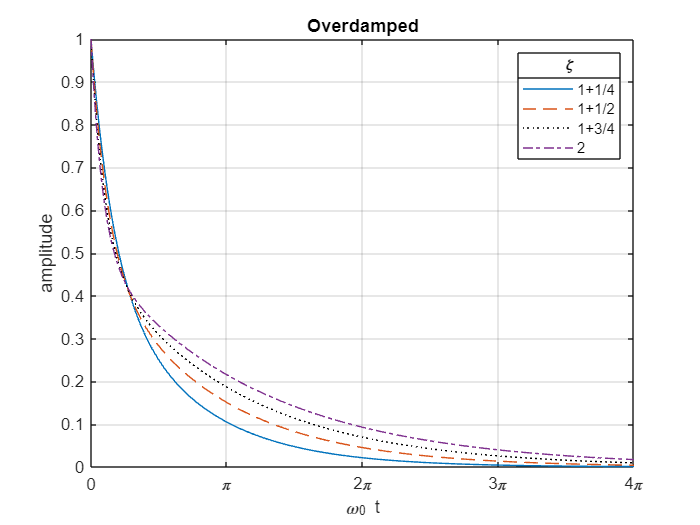

z = 1 + [1/4 1/2 3/4 1];
w = 1;
T = 4*pi;
lineStyle = {'-','--',':k','-.'};

fplot(@(t)solOver(t, w, z(1)), [0 T], lineStyle{1});

hold on;
for k = 2:numel(z)
    fplot(@(t)solOver(t, w, z(k)), [0 T], lineStyle{k});
end
hold off;
grid on;
xticks(T*linspace(0,1,5));
xticklabels({'0','\pi','2\pi','3\pi','4\pi'});
xlabel('\omega_0 t');
ylabel('amplitude');
lgd = legend('1+1/4','1+1/2','1+3/4','2');
title(lgd,'\zeta');
title('Overdamped');

## 5. Critically Damped Case ($\zeta = 1$)

If $\zeta = 1$, then the solution simplifies to

solCritical(t, omega_0) = limit(sol, zeta, 1)

$$solCritical(t, omega\_0) = {\mathrm{e}}^{-\omega_{0}\,t}\,\left(\omega_{0}\,t+1\right)$$

Plot the solution for the critically damped case.

w = 1;
T = 4*pi;

fplot(solCritical(t, w), [0 T])
xlabel('\omega_0 t');
ylabel('x');
title('Critically damped, \zeta = 1');
grid on;
xticks(T*linspace(0,1,5));
xticklabels({'0','\pi','2\pi','3\pi','4\pi'});

## 6. Conclusion

We have examined the different damping states for the harmonic oscillator by solving the ODEs which represents its motion using the damping ratio $\zeta$. Plot all three cases together to compare and contrast them.

zOver  = pi;
zUnder = 1/zOver;
w = 1;
T = 2*pi;
lineStyle = {'-','--',':k'};

fplot(@(t)solOver(t, w, zOver), [0 T], lineStyle{1},'LineWidth',2);
hold on;
fplot(solCritical(t, w), [0 T], lineStyle{2},'LineWidth',2)
fplot(@(t)solUnder(t, w, zUnder), [0 T], lineStyle{3},'LineWidth',2);
hold off;

textColor = lines(3);
text(3*pi/2, 0.3 , 'over-damped'      ,'Color',textColor(1,:));
text(pi*3/4, 0.05, 'critically-damped','Color',textColor(2,:));
text(pi/8  , -0.1, 'under-damped');

grid on;
xlabel('\omega_0 t');
ylabel('amplitude');
xticks(T*linspace(0,1,5));
xticklabels({'0','\pi/2','\pi','3\pi/2','2\pi'});
yticks((1/exp(1))*[-1 0 1 2 exp(1)]);
yticklabels({'-1/e','0','1/e','2/e','1'});
lgd = legend('\pi','1','1/\pi');
title(lgd,'\zeta');
title('Damped Harmonic Oscillator');

Copyright 2018 The MathWorks, Inc.